# PSTH app

set(groot, 'defaultTextInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');

load('monkeydata_training');
data = section(trial);

Select unit

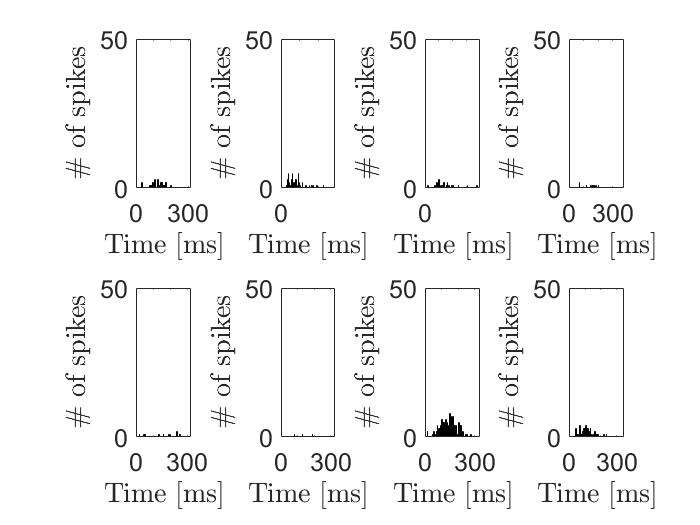

opt.unit =8;
figure;
for i = 1:1:8
    subplot(2,4,i);
    opt.angle = i;
    PSTH(data,opt,5,'show');
    ylim([0,50]);
end

Run this section to get the set of preferred angles for all units

 
for j = 1:1:98
    opt.unit = j;
    figure;
    for i = 1:1:8
        subplot(2,4,i);
        opt.angle = i;
        h = PSTH(data,opt,5,'no');
        ylim([0,23]);
        s(i) = sum(h.psth);
    end

    [~,out] = sort(s);
    unit(j).angle_order = flip(out);
end
close all

Run this section to plot the preferred angle across units from PSTH and tuning curve methods

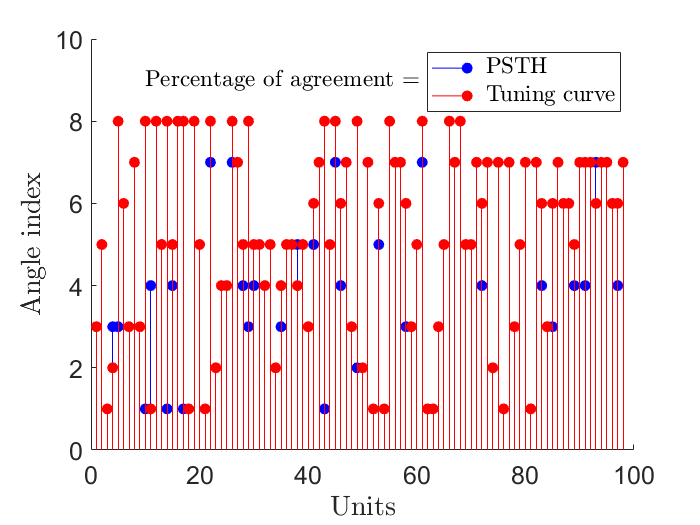

 
unit_clean = extractfield(unit,'angle_order');
unit_clean = unit_clean(1:8,:);
figure;
hold on;
stem(unit_clean(1,:),'filled','Color','b');
for i = 1:1:98
    P = tuning_curve(data,i,5,'count','no');
    p(i) = P.idx;
end
stem(p,'filled','Color','r');
ylim([0,10]);
per = sum(p==unit_clean(1,:))/98*100;
text(0.1,0.9,sprintf('Percentage of agreement = %2.3f',per),'Units','normalized','FontSize',14,'Interpreter','latex');
set(gca,'FontSize',15)
xlabel('Units','FontSize',20);
ylabel('Angle index','FontSize',20);
legend('PSTH','Tuning curve');